% way0 = [0, 275/2];
% way2 = [450, 275];
% way1 = [450, 275/2-10]
t = 0:0.001:1;

% wayx = way1(1) + (way0(1)-way1(1))*(1-t).^2 + (way2(1)-way1(1))*t.^2;
% wayy = way1(2) + (way0(2)-way1(2))*(1-t).^2 + (way2(2)-way1(2))*t.^2;


P0 = [-1500, 800, 10000];
% P2 = [100, 200];

P2x = 350;
P2y = 353;
P2z = 5000;
P2 = [P2x, P2y, P2z];

P1x =0;
P1y =-76;
P1z =5000;

P1 = [P1x, P1y, P1z];

ang = atan2d(P2(2)-P0(2), P2(1)-P0(1))

ang =  -13.583552705678837


des_head = -3.9;


start_head = 26;
format long;
bx = P1(1) + (P0(1)-P1(1))*(1-t).^2 + (P2(1)-P1(1))*t.^2;
by = P1(2) + (P0(2)-P1(2))*(1-t).^2 + (P2(2)-P1(2))*t.^2;
bz = P1(3) + (P0(3)-P1(3))*(1-t).^2 + (P2(3)-P1(3))*t.^2;

angle = atan2d(by(1000)-by(999), bx(1000)-bx(999));
disp('Final XY End Heading = ');

Final XY End Heading = 


% if angle > 90
%     angle= angle-180;
% end
disp(angle)

  50.524107259611100



angle = atan2d(bz(1000)-bz(999), bx(1000)-bx(999));
disp('Final ZX End Heading = ');

Final ZX End Heading = 


% if angle > 90
%     angle= angle-180;
% end
disp(angle)

  -1.221560123613631



angle = atan2d(bz(1000)-bz(999), by(1000)-by(999));
disp('Final ZY End Heading = ');

Final ZY End Heading = 


% if angle > 90
%     angle= angle-180;
% end
disp(angle)

  -1.006162554726088




des_head=angle;

l_y = P2(2)+10*sind(des_head);
l_x = P2(1)+10*cosd(des_head);
x = -1000:10:1000;

m = (l_y-P2(2))/(l_x-P2(1));
b = P2(2)-m*P2(1);
y = m.*x+b;

s_y = P0(2)+100*sind(start_head);
s_x = P0(1)+100*cosd(start_head);
x2 = 0:1:x(1);
m2 = (s_y-P0(2))/(s_x-P0(1));
b2 = P0(2)-m2*P0(1);
y2 = m2.*x2+b2;

% if m ~= m2
%     x_intersect = (b2 - b) / (m - m2);
%     y_intersect = m * x_intersect + b;
% 
%     fprintf('Intersection point: (%.2f, %.2f)\n', x_intersect, y_intersect);
% else
%     disp('The lines are parallel and do not intersect.');
% end
% % 
% 
% % 
% P1y = y_intersect;
% P1x = x_intersect;
% P1 = [P1x, P1y];
% bx = P1(1) + (P0(1)-P1(1))*(1-t).^2 + (P2(1)-P1(1))*t.^2;
% by = P1(2) + (P0(2)-P1(2))*(1-t).^2 + (P2(2)-P1(2))*t.^2;
% angle = atan2d(by(1000)-by(999), bx(1000)-bx(999));
% disp('Final End Heading = ');
% if angle > 90
%     angle= angle-180;
% end
% disp(angle)
disp('Desired End Heading = ');

Desired End Heading = 


disp(des_head)

  -1.006162554726088




angle = atan2d(by(2)-by(1), bx(2)-bx(1));
if angle > 90
    angle= angle-180;
end
disp('Final Start Heading = ')

Final Start Heading = 


disp(angle)

 -30.275903520461345



disp('Desired Start Heading = ');

Desired Start Heading = 


disp(start_head)

    26




close;
% ylim([-1200, 800]);
zlim([4000, 11000])
% figure();
% clear;
fig = gcf;  % Get the current figure handle
ax = gca;   % Get the current axes handle

% if ~isappdata(ax, 'camData')
%     % Store initial camera settings only once
%     setappdata(ax, 'camData', struct( ...
%         'pos', campos, ...
%         'tar', camtarget, ...
%         'up', camup, ...
%         'ang', camva ...
%     ));
% else
%     % Retrieve stored camera settings
%     camData = getappdata(ax, 'camData');
%     campos(camData.pos);
%     camtarget(camData.tar);
%     camup(camData.up);
%     camva(camData.ang);
% end
% view([34 20]);
hold on;

% scatter3(P2(1), P2(2), P2(3), 'MarkerFaceColor', 'black')
scatter3(P0(1), P0(2), P0(3), 'MarkerFaceColor', 'green')
scatter3(P1x, P1y, P1z,'MarkerFaceColor', 'red')
% plot([P0(1), s_x], [P0(2), s_y], 'LineWidth', 2, 'Color', 'k', 'LineStyle','--')
axis('equal');
xlabel('X');
ylabel('Y');
zlabel('Z');

% plot([way1(1), P1(1)], [way1(2), P1(2)], 'LineWidth', 2)
% plot(wayx, wayy, 'LineWidth', 2, 'Color', 'k')
% plot([P1(1), way1(1)], [P1(2), way1(2)])
% plot(x, y, 'LineWidth', 2, 'Color', 'blue', 'LineStyle','--')
% plot(x2, y2, 'LineWidth', 2, 'Color', 'blue', 'LineStyle','--')
plot3(bx, by, bz, 'LineWidth', 2, 'Color', 'blue')

legend('P2', 'P0', 'P1', 'Bez')

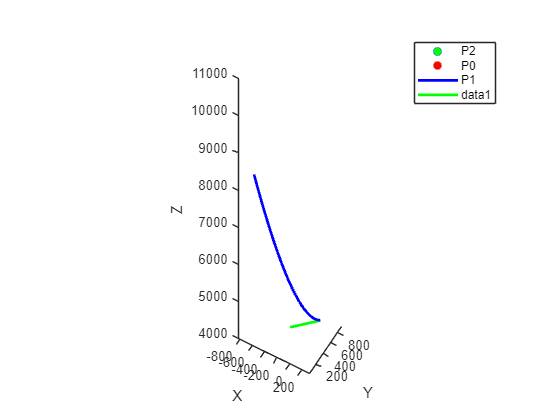

plot3([0, 1000], [0, 1000], [5000, 5000], 'LineWidth', 2, 'Color', 'green')
hold off;

% campos(cam_pos);     % Restore camera position
% camtarget(cam_tar);  % Restore camera target
% camup(cam_up);       % Restore camera up vector
% camva(cam_ang);      % Restore camera view angle


